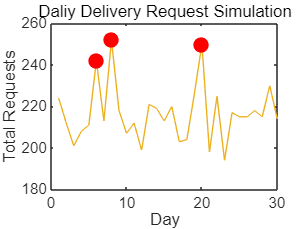

%1_(a)
rng(14);
%1_(b)
request = poissrnd(18, 30, 12);
%1_(c)
dailyTotal = sum(request, 2);
%1_(d)
busyDay = dailyTotal>=240;
%1_(e)
numBusyDay = sum(busyDay);
%1_(f)
hourlyMean = mean(request, 1);
%1_(g)
days = 1:30;
plot(days, dailyTotal);
hold on;
plot(days(busyDay), dailyTotal(busyDay), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
%1_(h)
xlabel('Day');
ylabel('Total Requests');
title('Daliy Delivery Request Simulation');

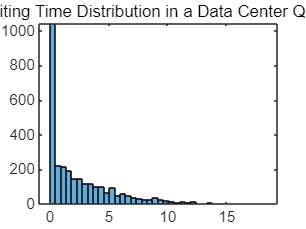

%2_(a)
n = 3000;
%2_(b)
interArrival = exprnd(1.2, 1, n);
%2_(c)
arrival = cumsum(interArrival);
%2_(d)
service = exprnd(0.9, 1, n);
%2_(e)
startTime = zeros(1, n);
finishTime = zeros(1, n);

startTime(1) = arrival(1);
finishTime(1) = startTime(1) + service(1);

for i = 2:n
    startTime(i) = max(finishTime(i-1), arrival(i));
    finishTime(i) = startTime(i) + service(i);
end
%2_(f)
waitingTime = startTime - arrival;
%2_(g)
meanWait = mean(waitingTime);
maxWait = max(waitingTime);
longWaitRatio = sum(waitingTime >= 5) / n;
%2_(h)
figure;
histogram(waitingTime, 40);
%2_(i)
title('Waiting Time Distribution in a Data Center Queue');

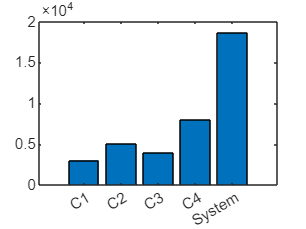

%3_(a)
n = 100000;
%3_(b)
c1 = rand(1, n) <= 0.97;
c2 = rand(1, n) <= 0.95;
c3 = rand(1, n) <= 0.96;
c4 = rand(1, n) <= 0.92;
%3_(c)
systemWorking = c1 & c2 & c3 & c4;
%3_(d)
reliabilityEst = sum(systemWorking) / n;
%3_(e)
reliabilityTrue = 0.97 * 0.95 * 0.96 * 0.92;
%3_(f)
absError = abs(reliabilityEst - reliabilityTrue);
%3_(g)
failCounts = [sum(~c1), sum(~c2), sum(~c3), sum(~c4), sum(~systemWorking)];
%3_(h)
figure;
bar(failCounts);
xticklabels({'C1', 'C2', 'C3', 'C4', 'System'});

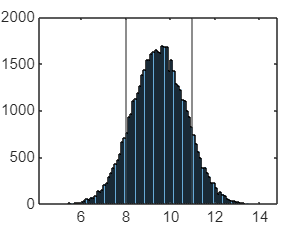

%4_(a)
batteryLife = normrnd(9.5, 1.2, 1, 50000);
%4_(b)
lowBattery = batteryLife < 8;
%4_(c)
normalBattery = batteryLife >= 8 & batteryLife < 11;
%4_(d)
excellentBattery = batteryLife >= 11;
%4_(e)
gradeCounts = [sum(lowBattery), sum(normalBattery), sum(excellentBattery)];
%4_(f)
gradeRatio = gradeCounts / 50000;
%4_(g)
figure;
histogram(batteryLife);

hold on;
xline(8);
xline(11);

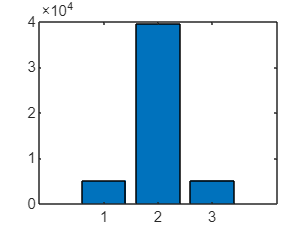

%4_(h)
figure;
bar(gradeCounts);

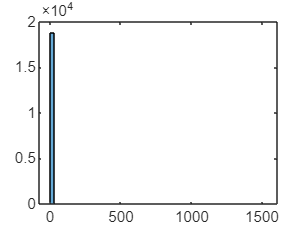

%5_(a)
n = 20000;
%5_(b)
hasClaim = rand(1, n) <= 0.06;
%5_(c)
claimAmount = normrnd(800, 250, 1, n);
%5_(d)
claimAmount(claimAmount < 0) = 0;
%5_(e)
claimPayment = hasClaim .* claimAmount;
%5_(f)
totalPayment = sum(claimPayment);
meanPayment = mean(claimPayment);
meanClaimOnly = mean(claimAmount(hasClaim));
%5_(g)
numLargeClaim = sum(claimPayment >= 1200);
%5_(h)
figure;
histogram(claimPayment);

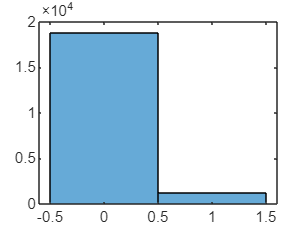

figure;
histogram(claimPayment > 0);

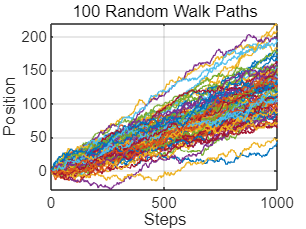

clc; clear;
%6_(a)
n = 1000;
m = 100;
%6_(b)
steps = 2 * (rand(n, m) <= 0.56) - 1;
%6_(c)
walks = cumsum(steps);
%6_(d)
figure;
plot(walks);
xlabel('Steps');
ylabel('Position');
title('100 Random Walk Paths');
grid on;

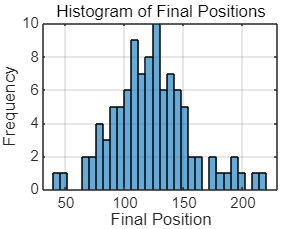

%6_(e)
finalPosition = walks(n, :);
%6_(f)
meanFinal = mean(finalPosition);
stdFinal = std(finalPosition);
%6_(g)
rightDriftRatio = sum(finalPosition >= 100) / m;
%6_(h)
figure;
histogram(finalPosition, 30);
xlabel('Final Position');
ylabel('Frequency');
title('Histogram of Final Positions');
grid on;

%7_(a)
rng(7);
%7_(b)
t = linspace(0, 30, 300);
%7_(c)
trueSignal = 2*sin(0.4*t) + 0.7*cos(1.5*t);
%7_(d)
obsSignal = trueSignal + normrnd(0, 0.25, 1, 300);
%7_(e)
idxNaN = randperm(300, 45);
obsSignal(idxNaN) = NaN;
%7_(f)
valid = ~isnan(obsSignal);
%7_(g)
recLinear = interp1(t(valid), obsSignal(valid), t, 'linear');
%7_(h)
recSpline = interp1(t(valid), obsSignal(valid), t, 'spline');
%7_(i)
rmseLinear = sqrt(mean((trueSignal - recLinear).^2));
rmseSpline = sqrt(mean((trueSignal - recSpline).^2));
%7_(j)
figure;
plot(t, trueSignal, 'k-', 'LineWidth', 1.5);
hold on;
plot(t, obsSignal, 'r.', 'MarkerSize', 8);
plot(t, recLinear, 'b--', 'LineWidth', 1);
plot(t, recSpline, 'g-.', 'LineWidth', 1);
xlabel('Time');
ylabel('Signal');
title('Signal Reconstruction using Interpolation');
legend('True Signal', 'Observed Signal (with NaNs)', 'Linear Interpolation', 'Spline Interpolation');
grid on;
hold off;

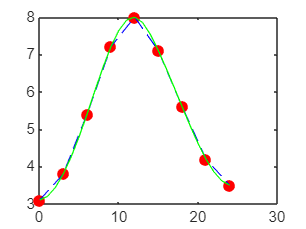

%8_(a)
timeObs = [0, 3, 6, 9, 12, 15, 18, 21, 24];
windObs = [3.1, 3.8, 5.4, 7.2, 8.0, 7.1, 5.6, 4.2, 3.5];
%8_(b)
timeHourly = 0:24;
%8_(c)
windLinear = interp1(timeObs, windObs, timeHourly, 'linear');
%8_(d)
windSpline = interp1(timeObs, windObs, timeHourly, 'spline');
%8_(e)
diffWind = windSpline - windLinear;
%8_(f)
maxDiff = max(abs(diffWind));
%8_(g)
figure;
plot(timeObs, windObs, 'ro', 'MarkerFaceColor', 'r');
hold on;
plot(timeHourly, windLinear, 'b--');
plot(timeHourly, windSpline, 'g-');
hold off;

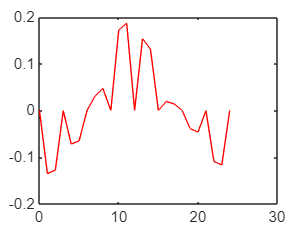

%8_(h)
figure;
plot(timeHourly, diffWind, 'r-');

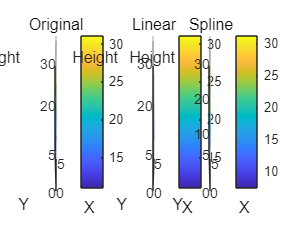

%9_(a)
[X, Y] = meshgrid(1:5, 1:5);
%9_(b)
H = [12 14 16 15 13; 13 18 22 20 16; 15 23 31 25 18; 11 15 26 16 17; 11 15 18 16 14];
%9_(c)
[Xq, Yq] = meshgrid(1:0.1:5, 1:0.1:5);
%9_(d)
HqLinear = interp2(X, Y, H, Xq, Yq, 'linear');
%9_(e)
HqSpline = interp2(X, Y, H, Xq, Yq, 'spline');
%9_(f)
figure;
tiledlayout(1, 3);
%9_(g)
nexttile;
surf(X, Y, H);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Height');
title('Original');
nexttile;
surf(Xq, Yq, HqLinear);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Height');
title('Linear');
nexttile;
surf(Xq, Yq, HqSpline);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Height');
title('Spline');

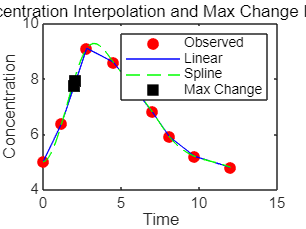

clc; clear;
%10_(a)
tobs = [0, 1.2, 2.8, 4.5, 7.0, 8.1, 9.7, 12.0];
cobs = [5.0, 6.4, 9.1, 8.6, 6.8, 5.9, 5.2, 4.8];
%10_(b)
tq = 0:0.1:12;
%10_(c)
cqLinear = interp1(tobs, cobs, tq, 'linear');
%10_(d)
cqSpline = interp1(tobs, cobs, tq, 'spline');
%10_(e)
deltaC = diff(cqLinear);
%10_(f)
[~, idxMaxChange] = max(abs(deltaC));
%10_(g)
changeInterval = [tq(idxMaxChange), tq(idxMaxChange+1)];
%10_(h)
figure;
plot(tobs, cobs, 'ro', 'MarkerFaceColor', 'r');
hold on;
plot(tq, cqLinear, 'b-');
plot(tq, cqSpline, 'g--');
plot(changeInterval, cqLinear(idxMaxChange:idxMaxChange+1), 'ks', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
xlabel('Time');
ylabel('Concentration');
title('Concentration Interpolation and Max Change Interval');
legend('Observed', 'Linear', 'Spline', 'Max Change');
hold off;

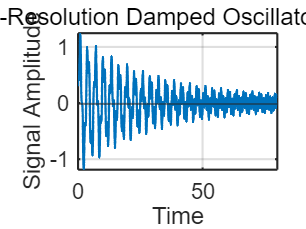

%11_(a)
t = linspace(0, 80, 12000);
%11_(b)
y = exp(-0.04*t).*sin(2*t) + 0.3*exp(-0.01*t).*cos(7*t);
%11_(c)
figure('Color', 'w');
%11_(d)
plot(t, y, 'LineWidth', 1.3);
%11_(e)
yline(0);
%11_(f)
xlabel('Time');
ylabel('Signal Amplitude');
title('High-Resolution Damped Oscillatory Signal');
%11_(g)
xlim([0 80]);
grid on;
box on;
%11_(h)
set(gca, 'FontSize', 12, 'LineWidth', 1.2);
%11_(i)
print('damped_signal.png', '-dpng', '-r300');

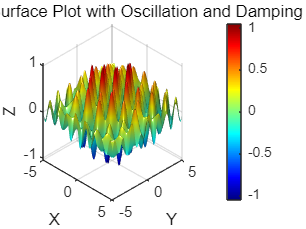

%12_(a)
x = linspace(-5, 5, 600);
y = linspace(-5, 5, 600);
%12_(b)
[X, Y] = meshgrid(x, y);
%12_(c)
Z = exp(-0.06*(X.^2 + Y.^2)).*sin(4*X).*cos(3*Y) + 0.2*sin(X.*Y);
%12_(d)
surf(X, Y, Z);
%12_(e)
shading interp;
colormap(jet);
colorbar;
%12_(f)
xlabel('X');
ylabel('Y');
zlabel('Z');
%12_(g)
title('Detailed Surface Plot with Oscillation and Damping');
%12_(h)
view(45, 30);
camlight headlight;
lighting phong;

%12_(i)
maxZ = max(Z(:));
minZ = min(Z(:));
%12_(j)
idxMax = find(Z == maxZ);
idxMin = find(Z == minZ);
maxPoint = [X(idxMax), Y(idxMax), Z(idxMax)];
minPoint = [X(idxMin), Y(idxMin), Z(idxMin)];

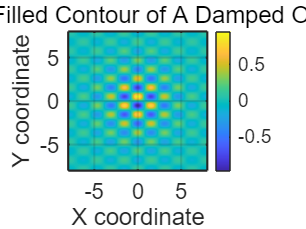

%13_(a)
x = linspace(-8, 8, 800);
y = linspace(-8, 8, 800);
%13_(b)
[X, Y] = meshgrid(x, y);
%13_(c)
Z = (cos(2*X).*sin(3*Y))./(1 + 0.1*(X.^2 + Y.^2));
%13_(d)
contourf(X, Y, Z, 70, 'LineColor', 'none');
%13_(e)
colormap(parula);
colorbar;
axis equal;
grid on;
box on;
%13_(f)
xlabel('X coordinate');
ylabel('Y coordinate');
%13_(g)
title('High-Resolution Filled Contour of A Damped Oscillatory Field');
%13_(h)
set(gca, 'FontSize', 12, 'LineWidth', 1.2);

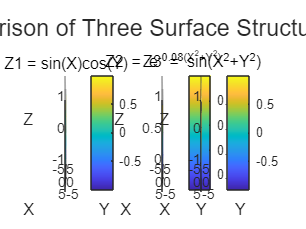

%14_(a)
x = linspace(-4, 4, 300);
y = linspace(-4, 4, 300);
%14_(b)
[X, Y] = meshgrid(x, y);
%14_(c)
Z1 = sin(X).*cos(Y);
Z2 = exp(-0.08*(X.^2 + Y.^2));
Z3 = sin(X.^2 + Y.^2);
%14_(d)
t = tiledlayout(1, 3);
%14_(e)
nexttile;
surf(X, Y, Z1);
%14_(f)
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Z1 = sin(X)cos(Y)');
%14_(g)
view(45, 30);
%14_(e)
nexttile;
surf(X, Y, Z2);
%14_(f)
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Z2 = e^{-0.08(X^2+Y^2)}');
%14_(g)
view(45, 30);
%14_(e)
nexttile;
surf(X, Y, Z3);
%14_(f)
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Z3 = sin(X^2+Y^2)');
%14_(g)
view(45, 30);
%14_(h)
title(t, 'Comparison of Three Surface Structures');

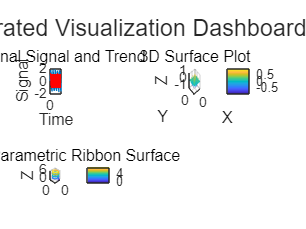

%15_(a)
u = linspace(0, 8*pi, 500);
v = linspace(-pi, pi, 180);
%15_(b)
[U, V] = meshgrid(u, v);
%15_(c)
X = (2 + 0.4*cos(V)).*cos(U);
Y = (2 + 0.4*cos(V)).*sin(U);
Z = 0.25*U + 0.4*sin(V);
%15_(d)
surf(X, Y, Z);
%15_(e)
shading interp;
colormap(parula);
colorbar;
%15_(f)
xlabel('X');
ylabel('Y');
zlabel('Z');
%15_(g)
title('Twisted Parametric Ribbon Surface');
%15_(h)
axis equal;
axis tight;
grid on;
view(45, 35);
%15_(i)
print('twisted ribbon.png', '-dpng', '-r300');

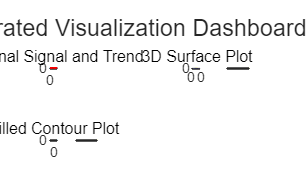

clc; clear;
%16_(a)
rng(3);
%16_(b)
t = linspace(0, 60, 6000);
signal = sin(0.5*t) + 0.4*sin(3*t) + 0.15*normrnd(0, 1, 1, 6000);
%16_(c)
trend = movmean(signal, 200);
%16_(d)
x = linspace(-5, 5, 300);
y = linspace(-5, 5, 300);
[X, Y] = meshgrid(x, y);
%16_(e)
Z = exp(-0.05*(X.^2 + Y.^2)).*cos(3*X).*sin(2*Y);
%16_(f)
fig = tiledlayout(2, 2);
%16_(g)
nexttile;
plot(t, signal);
hold on;
plot(t, trend, 'r', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Signal');
title('Original Signal and Trend');
grid on;
hold off;
%16_(h)
nexttile;
surf(X, Y, Z);
shading interp;
colorbar;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Surface Plot');
%16_(i)
nexttile;
contourf(X, Y, Z, 50, 'LineColor', 'none');
colorbar;
xlabel('X');
ylabel('Y');
title('Filled Contour Plot');
%16_(k)
title(fig, 'Integrated Visualization Dashboard');
%16_(l)
print('visualization_dashboard.png', '-dpng', '-r300');